# Algoritmos Numéricos por Computadora

# Primer parcial - Primavera 2020

Cambia el nombre del script a NombreClaveúnica (ej: Marcelo123456).

Sube tu archivo resultado a comunidad $\to$ primerParcial antes de las 10am.

## Formato IEEE 754. Punto flotante de doble precisión.

1. [2 puntos] 

a) Explica a detalle la representación hexadecimal del número 2.125  en el  formato IEEE 754: $x=\mathrm{signo}\;\left(1+f\right)2^e$. En el siguiente código inserta tus observaciones y cálculos para determinar: *signo*, *e*, *f *y *x*. 

% Escribe aquí tus observaciones y cálculos
i = 1:13;
vectorAux=[(1./(16.^i))];
xri = num2hex(2.125)

xri = '4001000000000000'

be = hex2dec('400')

be =         1024


signo = 1

signo =      0


e = be - 1023

e =      1


f = sum([1,0,0,0,0,0,0,0,0,0,0,0,0].*vectorAux)

f =    0.062500000000000


x = signo*(1+f)*(2^e)

x =    2.125000000000000


b) Repite ejercicio anterior pero ahora con el número -1.1

xri2 = num2hex(-1.1)

xri2 = 'bff199999999999a'

be = hex2dec('3ff') % use 3 en lugar de b porque b = 1011 

be =         1023


% y el primer 1 es el bit de signo, por lo tanto be empieza
% con 011 = 3
signo = -1

signo =     -1


e = be - 1023

e =      0


f = sum([1,9,9,9,9,9,9,9,9,9,9,9,10].*vectorAux)

f =    0.100000000000000


x = signo*(1+f)*(2^0)

x =   -1.100000000000000


## Raíces de funciones

2. [2 puntos] Considera un tanque esférico de radio R. El volumen del líquido contenido en el tanque es función de la altura h:


$$V=\pi h^2 \left(\frac{3R-h}{3}\right)$$


Calcula a qué altura hay que llenar un tanque de radio R=3 *m* para tener un volumen V= 30 $m^3$. 

Utiliza el método de la secante (escribe el código más abajo) o utiliza la función fzero de Matlab.

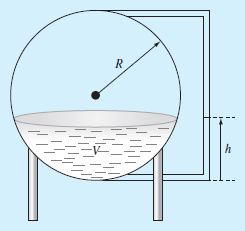

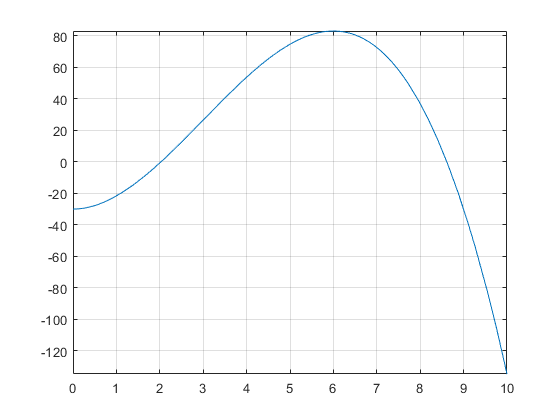

% El código no debe generar warnings
format long
r = 3;
v = @(h) (pi*(h.^2)).*(((3*r)-h)/3) - 30;
fplot(v,[0,10]);
grid on

%Como se puede observar en la gráfica, hay dos puntos
%en los que la función se hace cero. Sin embargo, sabemos
%que el volumen máximo de la esfera planteada es 113.0973 m^3
%Es decir, el valor máximo de la función es 83.0973. Por
%lo tanto, se considerará únicamente la primera raíz
[h,i] = secante(v,1.5,2.5)

h =    2.026905728310013


i =      7


3. [2 puntos] Determina todas las raíces de $f\left(x\right)=-14-20x+19x^2 -3x^3$. Grafica el polinomio para identificar en qué regiones se encuentran las raíces.

% El código no debe generar warnings
f = @(x) (-3*x.^3)+(19*x.^2)-(20*x)-14;

f = function_handle with value:
    @(x)(-3*x.^3)+(19*x.^2)-(20*x)-14


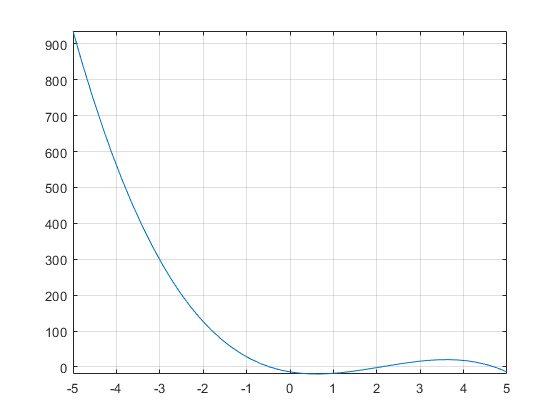

fplot(f,[-5,5])
grid on

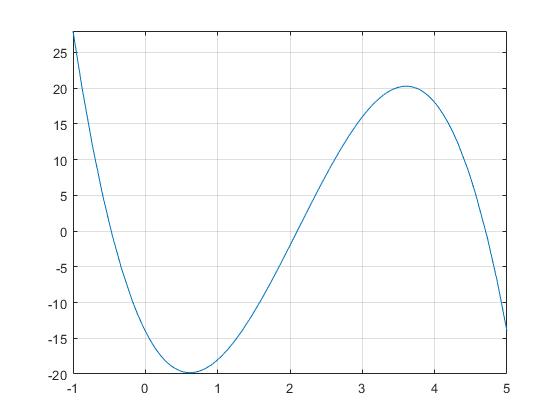

%en esta primera vez que graficamos podemos ver que
%hay tres raíces entre -1 y 5 por lo que las
%buscaremos más de cerca
fplot(f,[-1,5])
grid on

%En este acercamiento se aprecian las tres raíces y 
%los intervalos en dónde buscarlos. Sabemos además
%que un polinomio de grado n tiene, como máximo, n
%raíces, por lo que estamos seguros que tenemos todas
[x1,i] = secante(f,-0.7,-0.3)

x1 =   -0.472291426483245


i =      7


f(x1)

ans =      0


[x2,i] = secante(f,1.7,2.3)

x2 =    2.099651913861615


i =      5


f(x2)

ans =      0


[x3,i] = secante(f,4.5,4.8)

x3 =    4.705972845954963


i =      7


f(x3)

ans =      0



%Estas gráficas se utiizaron para reducir aún más 
%los intervalos
%fplot(f,[-1,0])
%grid on
%fplot(f,[1.5,2.5])
%grid on
%fplot(f,[4.5,5])
%grid on



## Optimización

4. [2 puntos] Encuentra el máximo de la función


$$f\left(x\right)=2\mathrm{sin}\left(x\right)-\frac{x^2 }{10}$$


en el intervalo [0,5].

Utiliza el método de Newton (escribe el código más abajo) o utiliza la función fminbnd de Matlab.

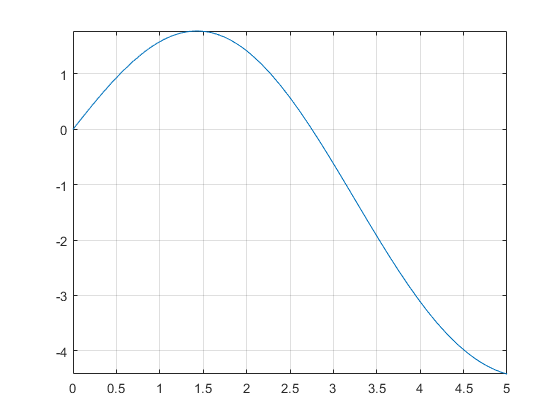

% El código no debe generar warnings
g = @(x) 2.*sin(x)-(x.^2/10);
fplot(g,[0,5])
grid on

[x,i,min] = NewtonOptimizacion(g,1)

x =    1.427551778764594


i =      4


min = logical
   0


5. [1 punto] Método de la secante.

function [x,i] = secante(f,a,b)
% Computes approximate solution of f(x)=0
% Input: function handle f; a,b such that a<b 
% Output: Approximate solution x
  i = 0;
  rtol = eps;
  cond = true;
    
  while cond
     fb = f(b);
     fa = f(a);
     x =  b - (fb/((fb - fa)/(b-a)));
     b = a;
     a = x;
     i = i+1;
     cond = abs(b-a)> rtol*abs(a) && i < 1000;
  end

end

6. [1 punto] Método de Newton para encontrar puntos críticos. 

Observa que la función debe regresar tres resultados. La variable min indíca si el punto crítico es un mínimo o un máximo.

function [x,i, min] = NewtonOptimizacion(f,x)
% Supone funciones doblemente diferenciables
% Encuentra un punto crítico de f
% min - indica si se trata de un mínimo (true) o máximo (false)
    fsym = sym(f);
    dfs = diff(fsym);
    df = matlabFunction(dfs);

    dfs2 = diff(dfs);
    df2 = matlabFunction(dfs2);
    
    rtol = sqrt(eps);
    MAX = 100;
    i = 0;
    cond = true;

    while cond
        xp = x;
        x = xp - (df(xp)/df2(xp));
        i = i + 1;
        cond = abs(x-xp)> abs(x)*rtol && i < MAX; 
    end

    min = (f(x)-f(xp))<0;
end